system1 = @(x) filter([1 zeros(1,round(0.4*samplerate) - 1) 0.7],1,x);
samplerate = 16e3;
t = (-4:1/samplerate:4);
omega = 27;
x1 = cos(omega*t);
y1 = system1(x1);
Re = 1+0.7*cos(10.8)

Re = 0.8640

Im = 0.7*(-sin(10.8))

Im = 0.6867

A = sqrt(Re^2+Im^2)

A = 1.1036

phi = atan(Im/Re)

phi = 0.6715

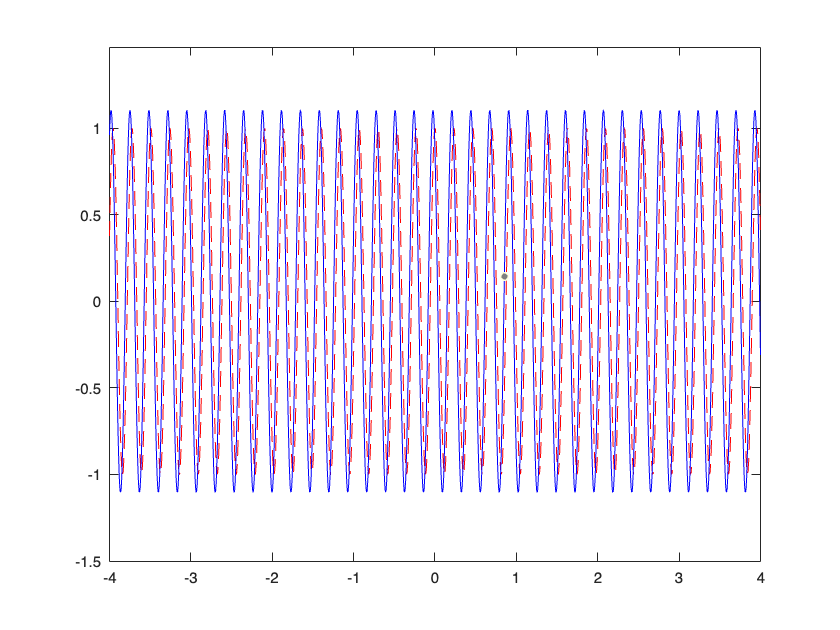


x_teorico = A*cos(omega*t+phi);
plot(t, x1, "r--"); hold on
plot(t, x_teorico, "b"); hold on